clc
close all
clear all

## Q4 Telephone

phone = [1,   2, 3;
         4,   5, 6;
         7,   8, 9;
         nan, 0, nan];

r = randi([1,10],1) - 1; %b/c randii range can only start at one, need to minus one

[m,n] = find(phone == r); %row and column of random number

switch m
    case 1
        f1 = 697
    case 2
        f1 = 770
    case 3
        f1 = 852
    case 4
        f1 = 941
end

f1 = 697


switch n
    case 1
        f2 = 1209
    case 2
        f2 = 1336
    case 3
        f2 = 1477
end

f2 = 1477

t_min = 0;
t_max = 16e-3;
t_size = abs(t_min) + abs(t_max);
Fs = 2^15; %sampling frequency
ttl_smpl=round(Fs*t_size);
t = linspace(t_min,t_max,ttl_smpl);

A = 0.25; %volume of tone
s1 = A*sin(2*pi*f1*t);
s2 = A*sin(2*pi*f2*t);
%noise = 

y = s1 + s2;
tone = y;

%expand tone to play for one second
for i = 1:round(1/t_size)
    tone = [tone y];
end

sound(tone,Fs);

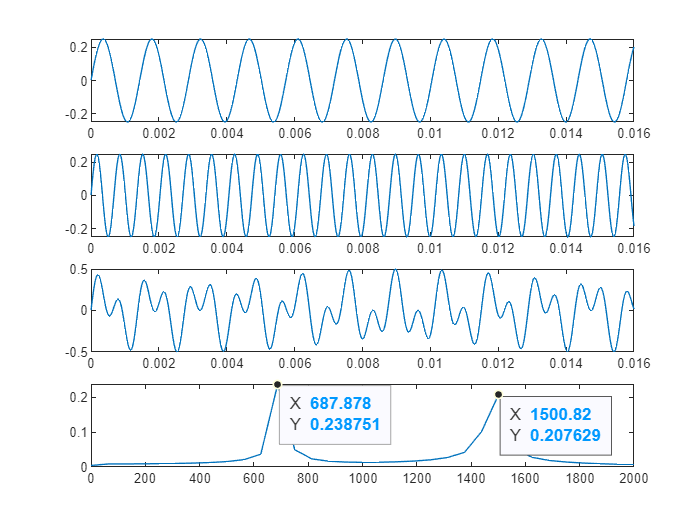

Y = fft(y); % to create from scratch

L = ttl_smpl;
%??
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

subplot(411)
plot(t,s1)

subplot(412)
plot(t,s2)

subplot(413)
plot(t,y)

subplot(414)
plot(f,P1)
xlim([0 2000])